# Simulation-Graph

## function import

addpath("./env/");
addpath("./env/map/");
addpath("./utils/");
addpath("./graph_search/");

## initialize

clear all;
clc;

% load environment
load("gridmap_20x20_scene1.mat");
map_size = size(grid_map);
G = 1;

% start and goal
start = [3, 2];
goal = [18, 29];

% planner
% planner_name = "a_star";
% planner_name = "gbfs";
planner_name = "dijkstra";

## path planning

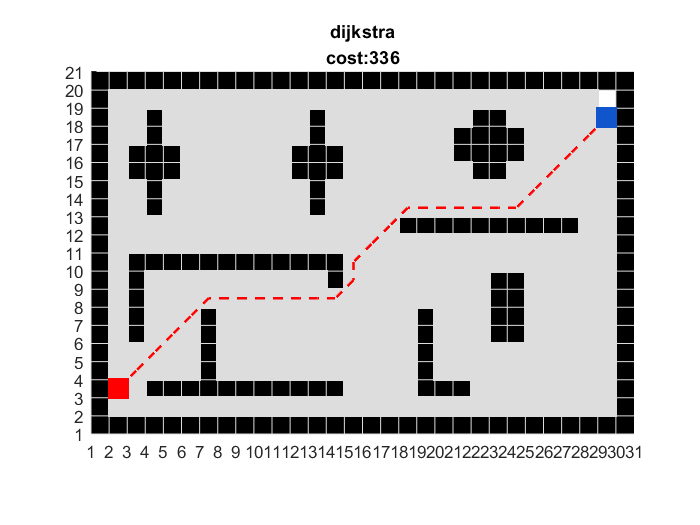

planner = str2func(planner_name);
[path, flag, cost, search] = planner(grid_map, start, goal);

% visualization
clf;
hold on

% plot grid map
plot_grid(grid_map);
% plot expand zone
plot_square(search, map_size, G, "#ddd");
% plot path
plot_path(path, map_size, G);
% plot start and goal
plot_square(start, map_size, G, "#f00");
plot_square(goal, map_size, G, "#15c");
% title
title([planner_name, "cost:" + num2str(cost)]);

hold off